## Exercise 1

#### Task 1

clearvars, clc, close all
load('EMG_Practical1.mat', 'SIG', 'ref_signal', 'fsamp');

Every row now has one EMG chanel in total 64, columns correspont to the duration of the task.

EMG = vertcat(SIG{:});

Plot all channels above each other.

figure, hold on
time = 0:1/fsamp:(length(EMG(1,:))-1)/fsamp;
length(time)

ans = 69540

length(EMG(1,:))

ans = 69540

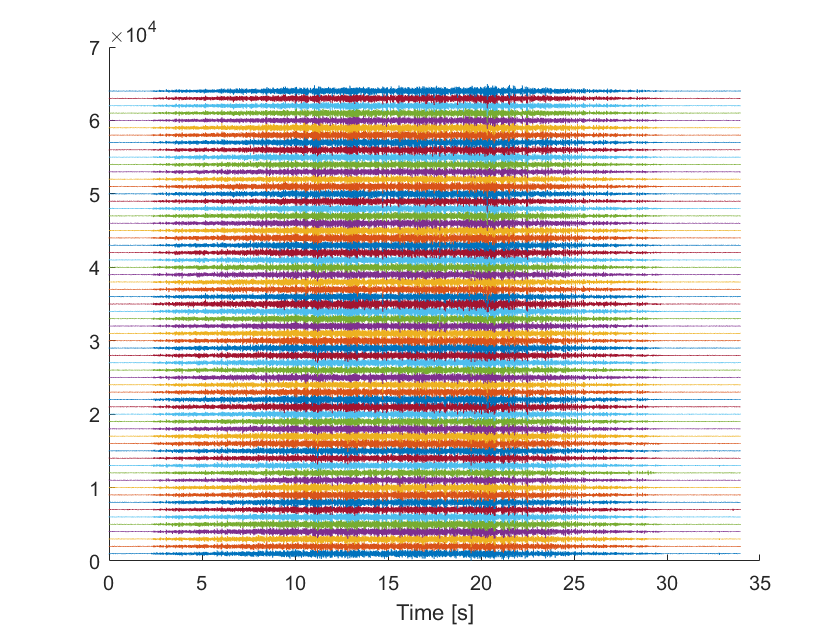

for k1 = 1:size(EMG, 1) 
    plot(time,EMG(k1,:)+k1*1000)
end

xlabel("Time [s]");
hold off

#### Task 2

Plot RMS of Channel 1

Duration: 0.05ms
Duration: 0.1ms
Duration: 0.2ms
Duration: 0.3ms
Duration: 0.4ms
Duration: 0.5ms


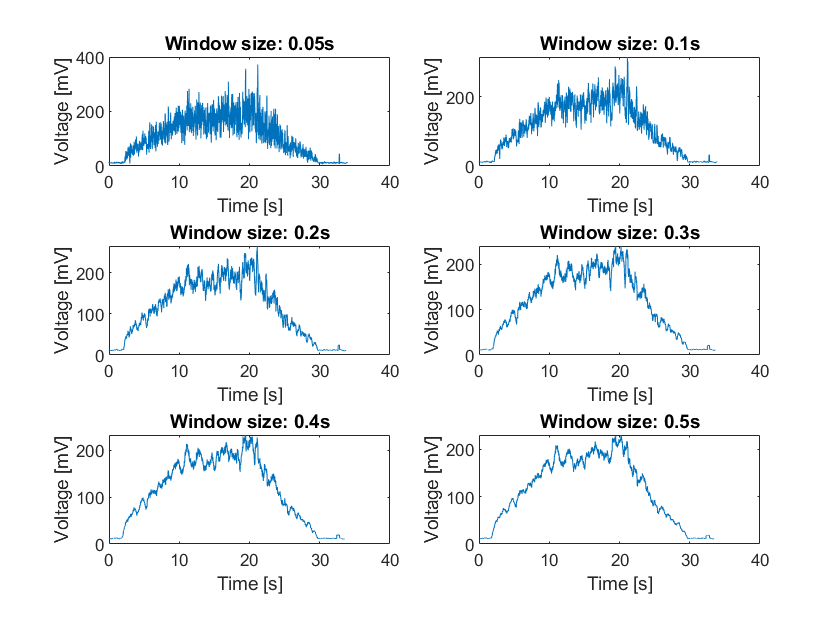

RMS1 = calculate_RMS(EMG, fsamp, 1);

#### Task 3

correlation = double.empty;
time = 0.05;
for i = 1:size(EMG, 1) 
    i
    RMS = calculate_RMS(EMG, fsamp, i);
    coef = corrcoef(RMS{1}, ref_signal(1:length(RMS{1})));
    correlation(end+1) = coef(2:2);   
end

i = 1

Unrecognized function or variable 'calculate_RMS2'.

bar(correlation);
x0=10;
y0=10;


width=1500;
height=400;
set(gcf,'position',[x0,y0,width,height]);
title("Correlation Coefficients for 0.2s" );

scatter(RMS{1}, ref_signal(1:length(RMS{1})));

Cannot find an exact (case-sensitive) match for 'RMS'

The closest match is: rms in C:\Program Files\MATLAB\R2021a\toolbox\signal\signal\rms.m

h = lsline;
set(h(1),'color','r')
B = [ones(size(h.XData(:))), h.XData(:)]\h.YData(:);
Slope = B(2)

i = 1

Duration: 0.2ms


i = 2

Duration: 0.2ms


i = 3

Duration: 0.2ms


i = 4

Duration: 0.2ms


i = 5

Duration: 0.2ms


i = 6

Duration: 0.2ms


i = 7

Duration: 0.2ms


i = 8

Duration: 0.2ms


i = 9

Duration: 0.2ms


i = 10

Duration: 0.2ms


i = 11

Duration: 0.2ms


i = 12

Duration: 0.2ms


i = 13

Duration: 0.2ms


i = 14

Duration: 0.2ms


i = 15

Duration: 0.2ms


i = 16

Duration: 0.2ms


i = 17

Duration: 0.2ms


i = 18

Duration: 0.2ms


i = 19

Duration: 0.2ms


i = 20

Duration: 0.2ms


i = 21

Duration: 0.2ms


i = 22

Duration: 0.2ms


i = 23

Duration: 0.2ms


i = 24

Duration: 0.2ms


i = 25

Duration: 0.2ms


i = 26

Duration: 0.2ms


i = 27

Duration: 0.2ms


i = 28

Duration: 0.2ms


i = 29

Duration: 0.2ms


i = 30

Duration: 0.2ms


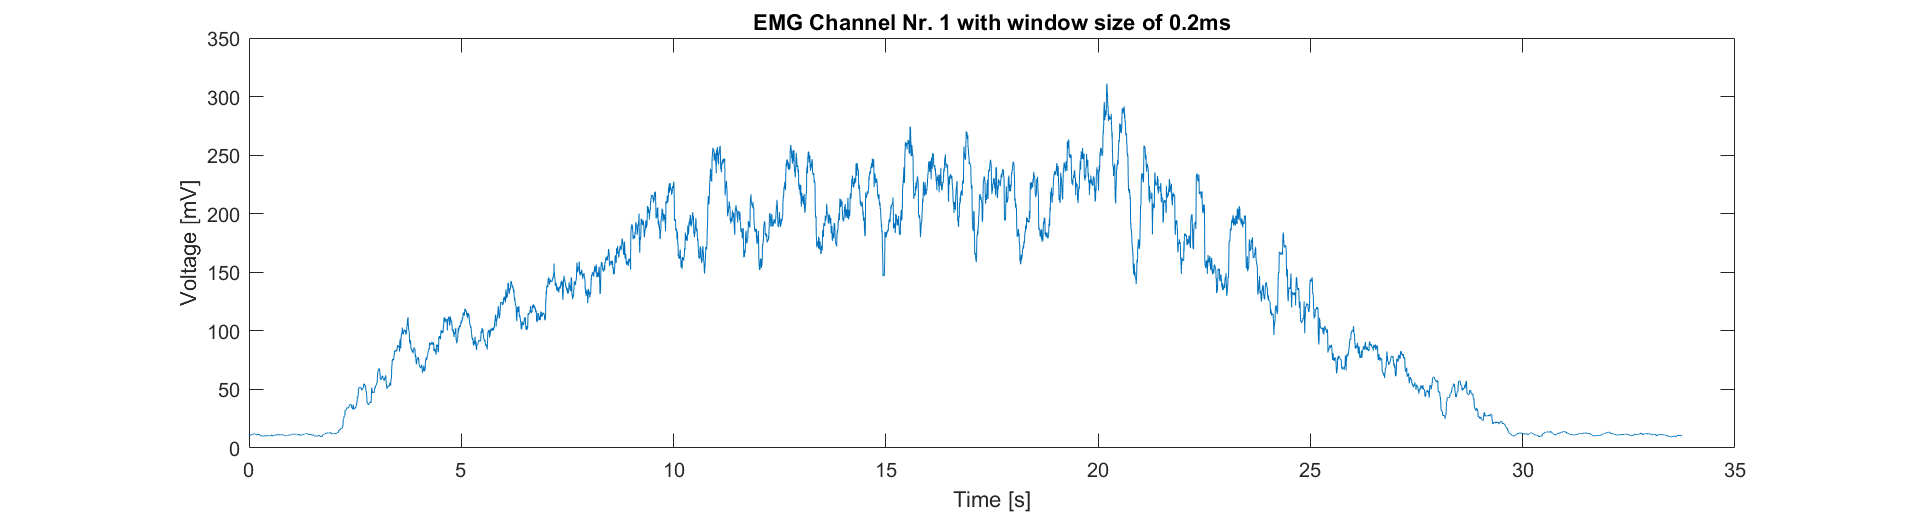

i = 31

correlation = double.empty;
%time = 0.05;
for i = 1:size(EMG, 1) 
    i
    RMS = calculate_RMS2(EMG, fsamp, i);
    coef = corrcoef(RMS{1}, ref_signal(1:length(RMS{1})));
    correlation(end+1) = coef(2:2);   
end


bar(correlation);
x0=10;
y0=10;
width=1500;
height=400;
set(gcf,'position',[x0,y0,width,height]);
title("Correlation Coefficients for 0.05ms" );

#### Functions

function [RMSs] = calculate_RMS(EMG, fsamp, channel)
    RMS = double.empty;
    RMSs = [];
    figure;
    %time_duration = [0.05];
    time_duration = [0.05, 0.1, 0.2, 0.3, 0.4, 0.5];
    for i= 1:length(time_duration)        
        number_samples = round(fsamp*time_duration(i));        
        start = 1;
        ende = number_samples;
        for j = 1:(length(EMG(channel,:)))
            if ende <= length(EMG(channel,:))
                signal = EMG(channel,start:ende);
                start = start+1;
                ende = ende+1;
                RMS(end+1) = rms(signal);     
            end
        end  
        disp("Duration: " + time_duration(i) + "ms");
        time =  0:1/fsamp:(length(RMS)-1)/fsamp;
        subplot(3,2,i);
        plot(time, RMS)
        title("Window size: " + time_duration(i) + "s")
        ylabel("Voltage [mV]")
        xlabel("Time [s]")        
        RMSs = [RMSs; {RMS}];
        RMS = double.empty;   
    end
end